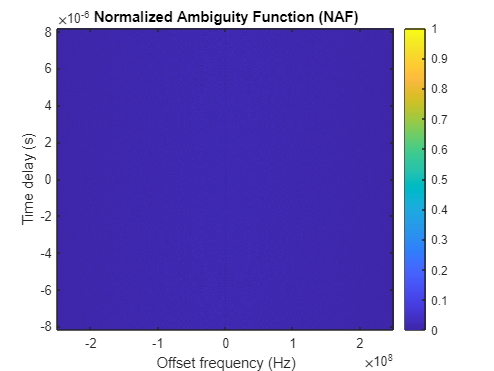

% Define M-sequence parameters
mSeqOrder = 12; % Order of the M-sequence
fs = 500e6; % Sample rate of the PRBS
mSeqLength = 2^mSeqOrder - 1; % Length of the M-sequence

% Generate M-sequence using Communications System Toolbox
hSeqGen = comm.PNSequence('Polynomial', [12 6 4 1 0], ...
                          'SamplesPerFrame', mSeqLength, ...
                          'InitialConditions', [1 zeros(1, mSeqOrder-1)]);
mSeq = step(hSeqGen);
mSeq = double(mSeq); % Convert logical to double for processing

% Convert M-sequence to bipolar (-1 and 1)
mSeqBipolar = 2 * mSeq - 1;

% Define the range of Doppler shifts and time delays for the ambiguity function
dopplerShifts = linspace(-fs/2, fs/2, mSeqLength);
ambFunc = zeros(length(dopplerShifts), 2*mSeqLength-1);

% Calculate the ambiguity function
for i = 1:length(dopplerShifts)
    % Apply Doppler shift by multiplying with a complex exponential
    dopplerShiftedSeq = mSeqBipolar .* exp(1j * 2 * pi * dopplerShifts(i) * (0:mSeqLength-1)' / fs);
    % Calculate cross-correlation with Doppler-shifted sequence
    ambFunc(i, :) = xcorr(dopplerShiftedSeq, mSeqBipolar);
end

% Normalize ambiguity function
ambFunc = abs(ambFunc);
ambFunc = ambFunc / max(ambFunc(:));

% Plot the ambiguity function
tGrid = (-mSeqLength+1):(mSeqLength-1);
tGrid = tGrid / fs; % Convert sample lags to time
figure;
imagesc(dopplerShifts, tGrid, ambFunc);
xlabel('Offset frequency (Hz)');
ylabel('Time delay (s)');
title('Normalized Ambiguity Function (NAF)');
colorbar;
axis xy;

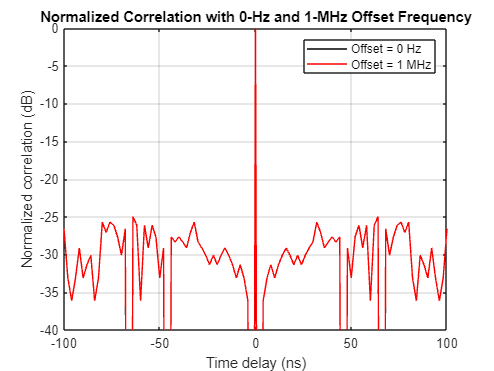




% Time vector for the sequence
N = length(mSeqBipolar);
timeVector = (0:N-1)'/fs;

% Define the frequency offsets for the correlation calculations
offsets = [0, 1e6];  % 0 Hz and 1 MHz

% Initialize vectors to store normalized correlations
normCorr0Hz = zeros(2*N-1, 1);
normCorr1MHz = zeros(2*N-1, 1);

% Calculate auto-correlation for the non-shifted sequence (0 Hz offset)
autoCorr = xcorr(mSeqBipolar);
normCorr0Hz = autoCorr / max(abs(autoCorr));

% Now for the 1 MHz offset, apply the frequency shift
freqOffset = offsets(2); % 1 MHz offset
mSeqShifted = mSeqBipolar .* exp(-1j*2*pi*freqOffset*timeVector);
autoCorrShifted = xcorr(mSeqShifted);
normCorr1MHz = autoCorrShifted / max(abs(autoCorrShifted));

% Prepare the time axis in nanoseconds for plotting
lags = (-N+1):(N-1);
timeLags = lags / fs * 1e9; % Convert to nanoseconds for the plot

% Plotting
figure;
plot(timeLags, 10*log10(abs(normCorr0Hz)), 'k'); % Zero offset in dB
hold on;
plot(timeLags, 10*log10(abs(normCorr1MHz)), 'r'); % 1 MHz offset in dB
xlabel('Time delay (ns)');
ylabel('Normalized correlation (dB)');
title('Normalized Correlation with 0-Hz and 1-MHz Offset Frequency');
legend('Offset = 0 Hz', 'Offset = 1 MHz');
xlim([-100, 100]); % Match the x-axis scale to the provided graph
ylim([-40, 0]); % Adjust the y-axis limits to match the scale in dB
grid on;
hold off;

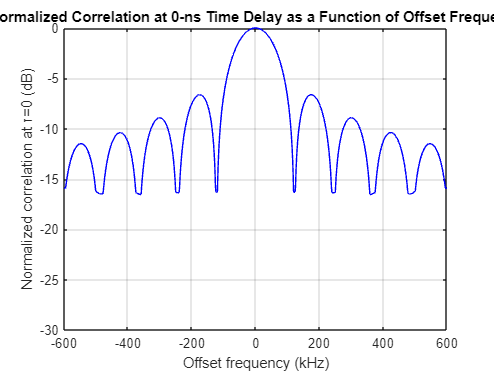




% Define frequency offsets in kHz
freqOffsets_kHz = linspace(-600, 600, 800) * 1e3; % From -400 kHz to 400 kHz


% Initialize the vector for the correlation at zero time delay
correlationAtZeroDelay = zeros(size(freqOffsets_kHz));

% Calculate the correlation for each frequency offset
for i = 1:length(freqOffsets_kHz)
    % Apply the frequency shift
    freqShift = freqOffsets_kHz(i);
    mSeqShifted = mSeqBipolar .* exp(-1j*2*pi*freqShift*timeVector);
    % Calculate the auto-correlation
    autoCorr = xcorr(mSeqBipolar, mSeqShifted);
    % Find the peak of the auto-correlation (at zero time delay)
    correlationAtZeroDelay(i) = max(abs(autoCorr));
end

% Normalize the correlation at zero time delay
normCorrelationAtZeroDelay = 10 * log10(correlationAtZeroDelay / max(correlationAtZeroDelay));

% Plotting
figure;
plot(freqOffsets_kHz/1e3, normCorrelationAtZeroDelay, 'b');
xlabel('Offset frequency (kHz)');
ylabel('Normalized correlation at τ=0 (dB)');
title('Normalized Correlation at 0-ns Time Delay as a Function of Offset Frequency');
xlim([-600, 600]); 
ylim([-30, 0]);
grid on;

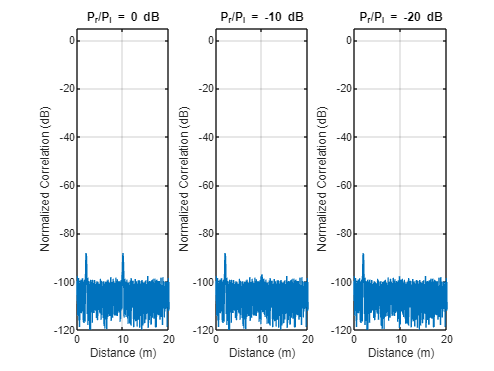

% Define simulation parameters
distances = linspace(0, 20, 2000); % Distance vector from 0 to 20 meters
internal_reflection_dist = 2; % Internal reflection at 2 meters
target_dist = 10; % Target at 10 meters
power_internal_reflection = 1.5e-9; % Power of internal reflection in watts (1.5 nW)

% Powers of the backscattered signal in watts, relative to internal reflection
power_backscattered = [1.5e-9, 0.15e-9, 0.015e-9];

% Noise level (consider practical SNR less than 15 dB)
noise_level = power_internal_reflection / 10^(15/10);

% Generate the internal reflection peak (Gaussian centered at 2m)
internal_reflection_signal = power_internal_reflection * exp(-((distances - internal_reflection_dist).^2) / (0.1^2));

% Generate noise
noise = noise_level * randn(1, length(distances));

% Initialize array to hold all signal values
signal = zeros(length(distances), length(power_backscattered));

% Generate signals for each power level of the backscattered signal
for i = 1:length(power_backscattered)
    % Backscattered signal (Gaussian centered at 10m)
    backscattered_signal = power_backscattered(i) * exp(-((distances - target_dist).^2) / (0.1^2));
    
    % Total signal is the sum of internal reflection, backscattered signal, and noise
    total_signal = internal_reflection_signal + backscattered_signal + noise;
    
    % Convert to dB scale for plotting, ensure no log of zero occurs
    signal(:, i) = 10 * log10(abs(total_signal) + 1e-12);
end

% Plot the results
figure;
for i = 1:length(power_backscattered)
    subplot(1, 3, i);
    plot(distances, signal(:, i));
    title(['P_r/P_i = ' num2str(10 * log10(power_backscattered(i) / power_internal_reflection)) ' dB']);
    xlabel('Distance (m)');
    ylabel('Normalized Correlation (dB)');
    ylim([-120 5]); 
    grid on;
end

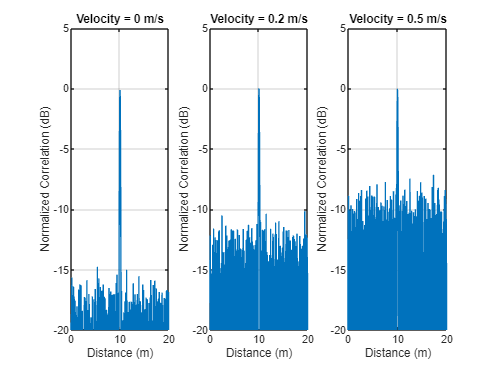

 % Define simulation parameters
 distances = linspace(0, 20, 2000); % Distance vector from 0 to 20 meters
 target_dist = 10; % Target at 10 meters
 power_backscattered = 1.5e-9; % Power of backscattered signal in watts (1.5 nW)
 velocities = [0, 0.2, 0.5]; % Velocities of the target in m/s
 % Base noise level corresponding to the lowest velocity
 base_noise_level = power_backscattered / 100; % Arbitrary choice to simulate a low SNR
 % Initialize array to hold all signal values
 signal = zeros(length(distances), length(velocities));
 % Generate signals for different target velocities
 for i = 1:length(velocities)
    % Adjust the noise level based on velocity to simulate DFS effect
    noise_level = base_noise_level * (1 + velocities(i) * 10); % Increasing noise with velocity
    
    % Backscattered signal (Gaussian peak)
    backscattered_signal = power_backscattered * exp(-((distances - target_dist).^2) / (0.1^2));
    
    % Add noise to the signal
    noisy_signal = backscattered_signal + noise_level * randn(size(backscattered_signal));
    
    % Make sure the signal stays above the noise floor
    noisy_signal = max(noisy_signal, base_noise_level);
    
    % Store the noisy signal
    signal(:, i) = noisy_signal;
 end
 % Plot the results
 figure;
 for i = 1:length(velocities)
    subplot(1, 3, i);
    % Convert to dB scale for plotting
    signal_db = 10 * log10(signal(:, i) / max(signal(:)));
    plot(distances, signal_db);
    title(['Velocity = ' num2str(velocities(i)) ' m/s']);
    xlabel('Distance (m)');
    ylabel('Normalized Correlation (dB)');
    ylim([-20 5]);
    grid on;
 end

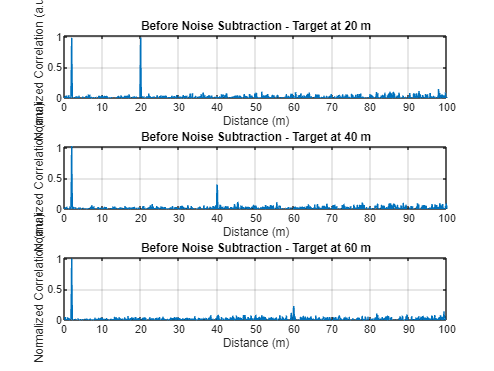

  % Define simulation parameters
 distances = linspace(0, 100, 1000); % Distance vector from 0 to 100 meters
 internal_reflection_dist = 2; % Internal reflection at 2 meters
 power_internal_reflection = 1; % Relative power of internal reflection
 % Powers of the backscattered signal in arbitrary units, relative to internal reflection
 power_backscattered = [1, 0.5, 0.25];
 % Generate the internal reflection peak (Gaussian centered at 2m)
 internal_reflection_signal = power_internal_reflection * exp(-((distances - internal_reflection_dist).^2) / (0.1^2));
 % Initialize array to hold all signal values
 signal = zeros(length(distances), length(power_backscattered));
 % Generate signals for each power level of the backscattered signal
 for i = 1:length(power_backscattered)
    % Backscattered signal (Gaussian centered at target distance)
    target_dist = 20 + (i-1)*20; % Target at 20, 40, 60 meters for each subplot
    backscattered_signal = power_backscattered(i) * exp(-((distances - target_dist).^2) / (0.1^2));
    
    % Total signal is the sum of internal reflection and backscattered signal
    total_signal = internal_reflection_signal + backscattered_signal;
    
    % Add noise, reducing its amplitude at the start of the signal
    noise_amplitude = 0.02 + 0.03 * (distances / max(distances)); % Increase noise amplitude over distance
    noise = noise_amplitude .* randn(size(distances));
    
    % Combine the total signal with noise
    signal(:, i) = total_signal + noise;
 end
 % Plot the results
 figure;
 for i = 1:length(power_backscattered)
    subplot(3, 1, i);
    plot(distances, signal(:, i));
    title(['Before Noise Subtraction - Target at ' num2str(20 + (i-1)*20) ' m']);
    xlabel('Distance (m)');
    ylabel('Normalized Correlation (a.u.)');
    ylim([0, max(signal(:))]);
    grid on;
 end

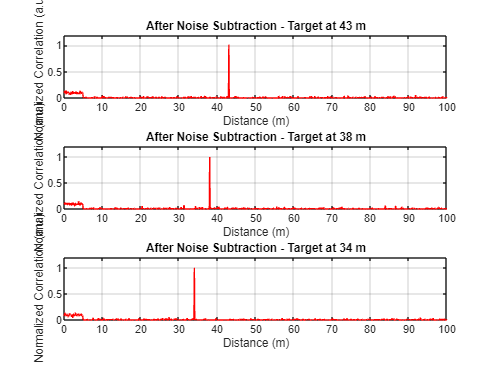

 % Define simulation parameters
 distances = linspace(0, 100, 1000); % Distance vector from 0 to 100 meters
 target_distances = [43, 38, 34]; % Target distances for each subplot
 
% Initialize array to hold all signal values
 signals = zeros(length(distances), length(target_distances));
 % Define noise parameters
 noise_amplitude = 0.02; % Amplitude of noise
 % Generate signals
 for i = 1:length(target_distances)
 % Add random noise to simulate the measurement variations
    noise = noise_amplitude * randn(1, length(distances));
 % Define the target signal (a spike at the target distance)
    target_signal = zeros(size(distances));
    [~, target_idx] = min(abs(distances - target_distances(i)));
    target_signal(target_idx) = 1; % Set a spike for the target
 % Combine noise and target signal
    signals(:, i) = target_signal + noise;
 % Simulate a higher signal-to-noise ratio at the start of the plot
    signals(1:50, i) = signals(1:50, i) + 0.1; % Increase signal at the beginning
 % Subtract estimated noise template (average noise level in this case)
    noise_template = mean(signals(:, i));
    signals(:, i) = signals(:, i) - noise_template;
 % Ensure no negative values
    signals(signals(:, i) < 0, i) = 0;
 end
 % Plot the results
 figure;
 for i = 1:length(target_distances)
    subplot(3, 1, i);
    plot(distances, signals(:, i), 'r');title(['After Noise Subtraction - Target at ' num2str(target_distances(i)) ' m']);
    xlabel('Distance (m)');
    ylabel('Normalized Correlation (a.u.)');
    ylim([0, 1.2]); 
    grid on;
 end

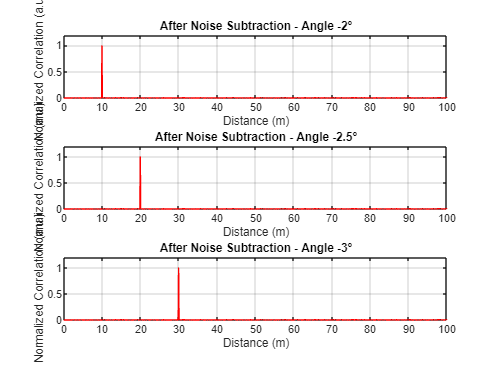

 % Define simulation parameters
 distances = linspace(0, 100, 1000); % Distance vector from 0 to 100 meters
 % Initialize array to hold all signal values
 signals = zeros(length(distances), 3); % Three subplots for three different angles
 % Simulate a lower level of noise
 noise_amplitude = 0.005; % Reduced amplitude of noise 
 % Generate noise
 noise = noise_amplitude * randn(1, length(distances));
 % Simulate that the noise template is subtracted from the signals
 for i = 1:3
    % Simulate sparse target signals
    target_signal = zeros(1, length(distances));
    target_signal(100 * i) = 1; % Place a single target for simplicity
    
    % Total signal is the sum of the target signal and noise
    signals(:, i) = target_signal + noise;
    
    % Subtract noise template (average noise level in this case)
    noise_template = mean(noise);
    signals(:, i) = signals(:, i) - noise_template;
    
    % Ensure no negative values
    signals(signals(:, i) < 0, i) = 0;
    
    % Reduce the signals around 0 m to simulate the noise subtraction effect
    signals(1:20, i) = signals(1:20, i) * 0.1;
 end
 % Plot the results
 figure;
 for i = 1:3
    subplot(3, 1, i);
    plot(distances, signals(:, i), 'r');
    title(['After Noise Subtraction - Angle ' num2str(-2 - 0.5*(i-1)) '°']);
    xlabel('Distance (m)');
    ylabel('Normalized Correlation (a.u.)');
    ylim([0, 1.2]); 
    grid on;
 end